# Generating a Codebook for a Multi-Array System

To obtain 360 degree coverage, many mobile systems use multiple arrays facing in different directions.  One of the challenges for such systems is the codebook design.  A *codebook* is a set of beamforming vectors on which the device can transmit or receive.  In millimeter wave systems, beam search is typically performed on a fixed set of these vectors.  Certain channel quality feedback mechanisms also use fixed codebooks.  With multiple arrays we want to make sure the codewords are well chosen to provide near uniform coverage over all the possible directions of arrival. In this demo, we show how to design such a codebook using a VQ type algorithm described in the paper:

- Xia, W., Semkin, V., Mezzavilla, M., Loianno, G., & Rangan, S. (2020, May). Multi-Array Designs for mmWave and Sub-THz Communication to UAVs. In *2020 IEEE 21st International Workshop on Signal Processing Advances in Wireless Communications (SPAWC)* (pp. 1-5)

 In going through this demo, we will learn how to:

- Set the path to find the `mmwsim` package

- Create and view an antenna element.

- Create a set of arrays with the elements and rotate the arrays

- Compute an optimized codebook for the arrays

- Plot the beamforming gain as a function of the angle of arrivals.

- Evaluate the performance of the codebook with test directions

## Theory

With multiple arrays, the codebook can be represented as an arrray, W,` of size nant x ncode x narr `where` nant` is the number of antenna elements in each array, `ncode` is the number of codewords and `narr` is the number of arrays.   Suppose that a signal arrives from an azimuth-elevation angle `(az,el)` .  Each array `k` will have some complex array response that can be represented by a vector:  `arrResp(:,k,az,el)` which includes the array element gain and steering vector.  If we select the `j` th codeword for array k, we will get a beamforming gain (in dBi) of:

The best beamforming gain among all codewords and arrays is:

When designing a codebook, we want to select `W` such that this optimal beamforming gain, `bfGainOpt(az,el)` is high for all possible angles `az, el` .  That is, whatever the direction of arrival of the plane wave, there is at least one array and one codeword on that array that can provide good beamforming gain.  The algorithm in the quoted paper above uses a k-means type algorithm to cluster the angular region into sub-sets and then select an optimal array and codeword for each region.  The method to perform this algorithm is provided in the `mmwsim` package and shown here.

## Adding the Package

We add the path for the `mmwsim` package.  After adding the path, we can access the contents with `mmwsim`.

% Add the folder containing +mmwsim to the MATLAB path.
addpath('../..');

## Creating a Patch Element

We will demonstrate the codebook design at 28 GHz.

% Compute the wavelength
fc = 28e9;
c=physconst('Lightspeed');
lambda = c/fc;

We next generate a simple patch antenna at this frequency.  We use MATLAB's excellent `design` tool which creates a patch antenna for a given resonat frequency.

% Design the antenna
ant = design(patchMicrostrip, fc);

We can display the antenna as follows.

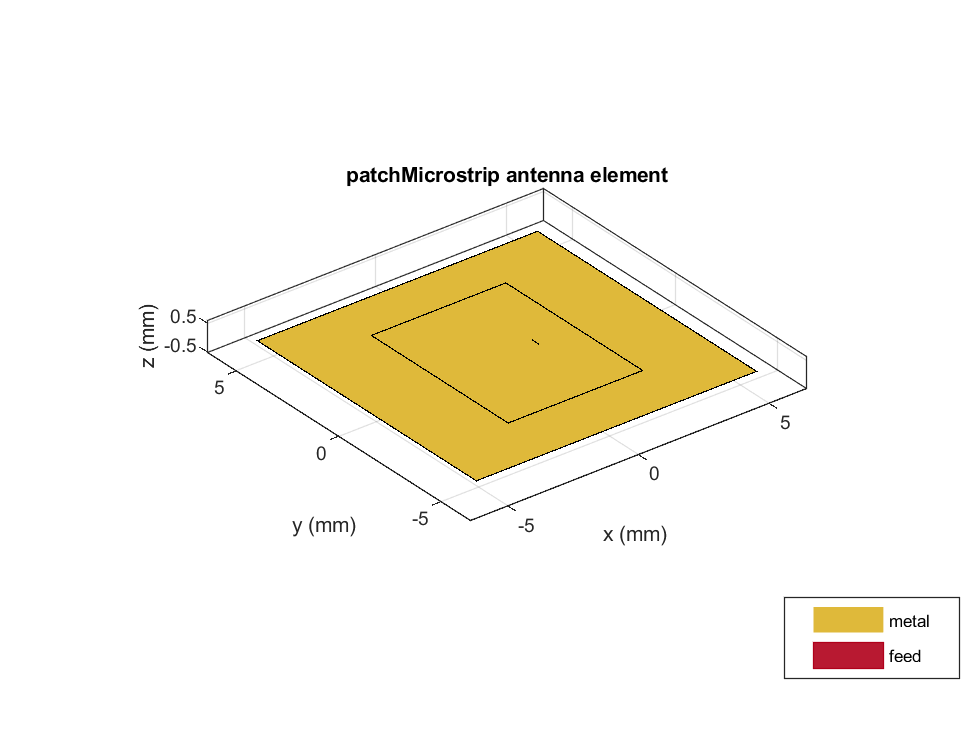

ant.show();

We rotate the antenna so that its boresight is on the x-axis by rotating the antenna on the y axis.  Note the use of the view command so that we can see the front face of the antenna.

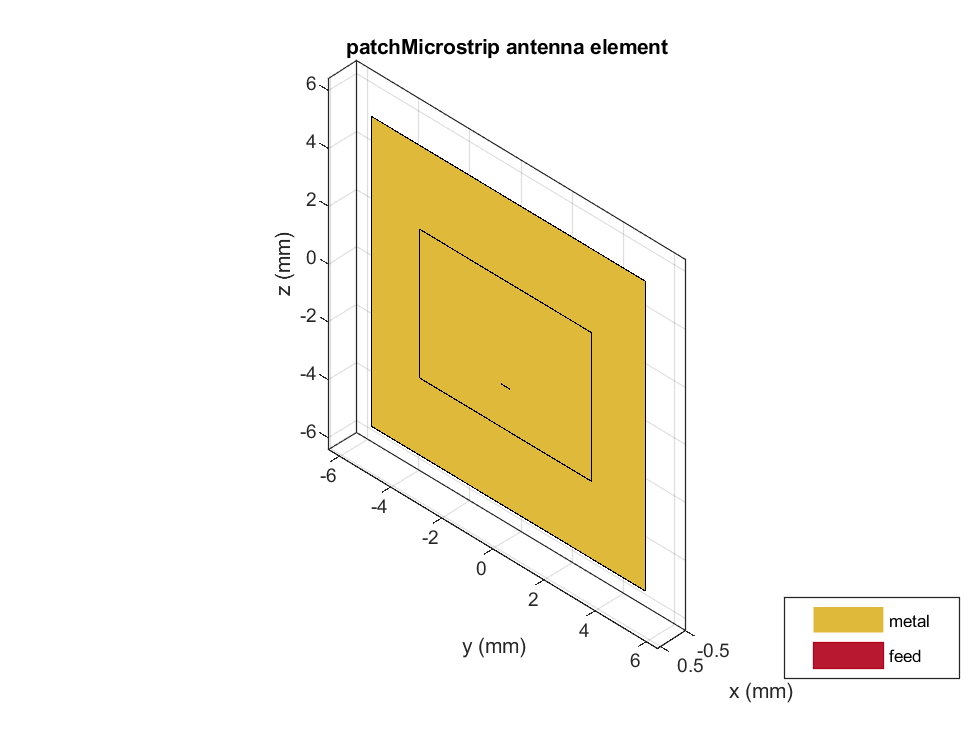

ant.set('Tilt', 90, 'TiltAxis', [0,1,0]);
ant.show();
view([135, 37]);

We now compute its pattern.  This may take a few minutes.  This is a highly directional element that has about 10.1 dBi of peak gain.

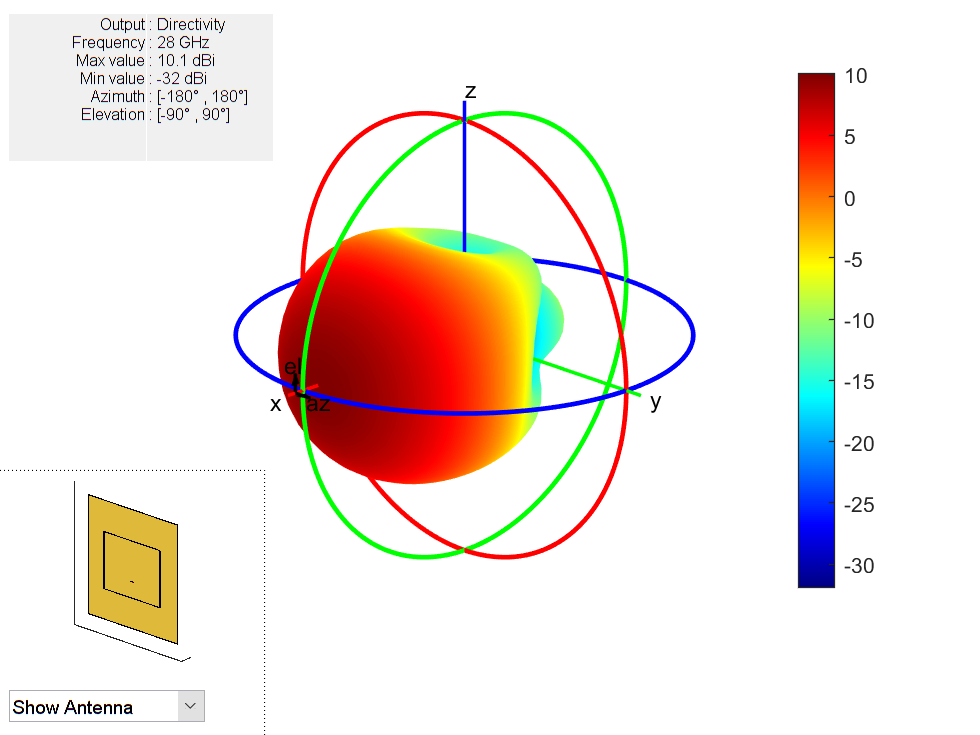

ant.pattern(fc);

## Creating the Array Set

To use the antenna element in the `mmwsim` package we need to wrap it in a class that interpolates the antenna pattern.

% Create wrapper class
elemInterp = mmwsim.antenna.InterpPatternAntenna(ant, fc);

We next create a base array containing the elements.  We will use a simple 4 x 4 URA directed in the x direction.

% The arrays are separated at lambda/2.
nantxy = [4,4];
dsep = 0.5*lambda;
arrBase  = phased.URA(nantxy,dsep,'ArrayNormal','x');

We now build a set of antenna arrays pointed in different directions.  The azimuth and elevation angle for each array are specified in the `azArr` and `elArr` vectors.

% Azimuth and elevation angles to point the arrays
azArr = [0, 120, -120];
elArr = [0, 0, 0];

% Create the set of arrays
narr = length(azArr);
arrSet = cell(narr,1);
for iarr = 1:narr
        
    % Create the array
    arri = mmwsim.antenna.ArrayPlatform('arr', arrBase, ...
    	'elem', elemInterp, 'fc', fc);
    
    % Align it to the desired direction
    arri.alignAxes(azArr(iarr), elArr(iarr));
    
    % Save the array in a list
    arrSet{iarr} = arri;
    
end

To show the orientation of the arrays, we plot the beam forming gain from each array using a zero phase codeword.  We can see that 

azPlot = (-180:2:180)';
elPlot = (-90:2:90)';
bfGain0 = zeros(nel, naz, narr);

for i = 1:narr
    % Set the BF direction to all one
    nant = arrSet{i}.arr.getNumElements();
    w0 = ones(nant,1)/sqrt(nant);
    
    % Get the 2D BF gain
    gain = arrSet{i}.getResponse2D(azPlot,elPlot, w0);
    bfGain0(:,:,i) = 20*log10(abs(gain));    
end

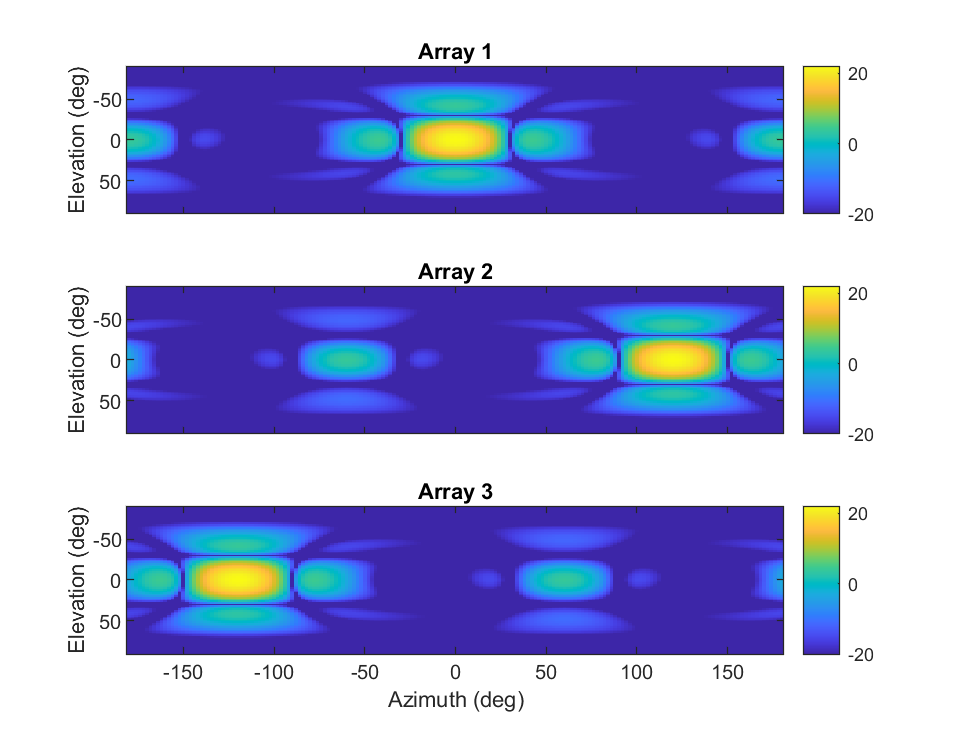

for i = 1:narr
    subplot(narr,1,i);
    mmwsim.antenna.plotPattern2D(azPlot,elPlot,max(-20,bfGain0(:,:,i)));
    if i < narr
        set(gca,'XTickLabel', []);
    else
        xlabel('Azimuth (deg)')
    end
    ylabel('Elevation (deg)');
    title(sprintf('Array %d', i));
end

## Designing the Codebook using the VQ Algorithm

We now design a codebook for the array.  We will set the number of codebook words to twice the number of antennas.

nant = prod(nantxy);  % number of antenna elements in each array
ncode = 2*nant;       % number of codewords

% Construct the codebook generator object
cb = mmwsim.antenna.Codebook('arrSet', arrSet, 'ncode', 32);
cb.genCodebook();

% Get the generated codebook
W = cb.W;

We can see that size of the codebook is `nant x ncode x narr `as explained above.

disp(size(W));

    16    32     3



We next compute the gain response on each array and codeword.  We then compute the maximum gain across the codewords and arrays.


% Beamforming gain in each direction
bfGainArr = zeros(nel,naz,narr);

for i = 1:narr
    
    % Compute the BF gain in each codeword
    gain = arrSet{i}.getResponse2D(azPlot, elPlot,W(:,:,i));
    bfGainW = 20*log10(abs(gain));
    
    % Maximize over all codewords in the array
    bfGainArr(:,:,i) = max(bfGainW, [], 1);
end

% Compute the max gain
bfGainMax = max(bfGainArr, [], 3);

Now we plot the gain on each array and the maximum gain across all three arrays.

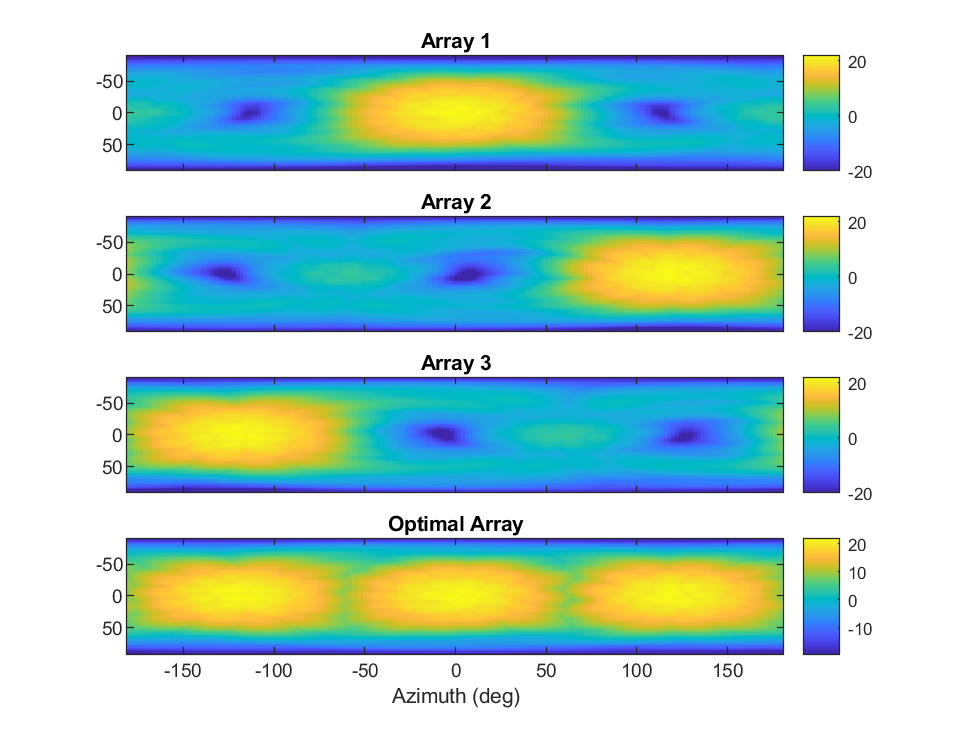

for i = 1:narr+1
    subplot(narr+1,1,i);
    if (i <= narr)
        mmwsim.antenna.plotPattern2D(azPlot,elPlot,max(-20,bfGainArr(:,:,i)));
        title(sprintf('Array %d', i));
    else
        mmwsim.antenna.plotPattern2D(azPlot,elPlot,max(-20,bfGainMax));
        title('Optimal Array');
    end
    if i < narr+1
        set(gca,'XTickLabel', []);
    else
        xlabel('Azimuth (deg)')
    end
end

## Evaluating the Codebook Performance

To evaluate the performance of the codebook, we generate a set of random angles.

% Generate the directions
ntest = 1000;
d = 3;
X = randn(ntest,d);

% Compute angles
[azTest, elTest, ~] = cart2sph(X(:,1), X(:,2), X(:,3));
azTest = rad2deg(azTest)';
elTest = rad2deg(elTest)';

We now compute the BF gains along each test direction.  We look at two orientations:  

-  the elevation angle is zero 

-  the actual elevation angle.

The first orientation is useful for the case when we know that the device can be positioned in the correct vertical orientation.  We see that the codebooks in this case provide good azimuth coverage.  The median beamforming gain is about 18 dBi.  But, when the elevation angle is random, there about a 7% chance the gain is less than zero.

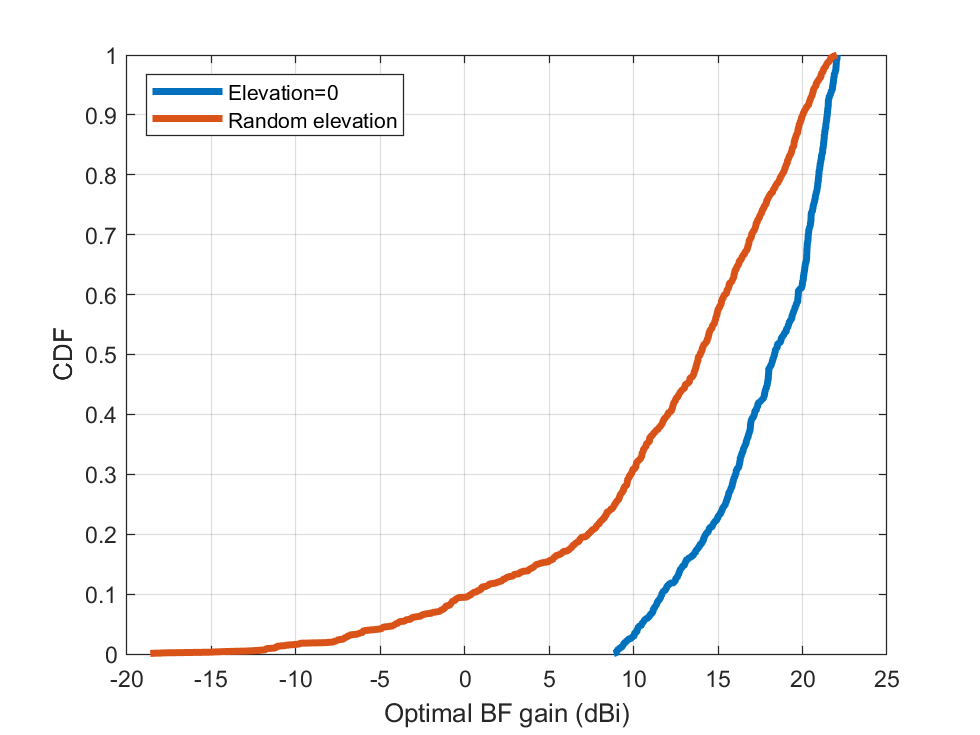

clf;
norient = 2;
bfGainMax = zeros(ntest,norient);

for iorient = 1:norient
    bfGainArr = zeros(ntest,narr);
    if iorient == 1
        el = zeros(1,ntest);
    else
        el = elTest;
    end
    
    for i = 1:narr
        
        % Compute the BF gain in each codeword
        gain = arrSet{i}.getResponse(azTest, el, W(:,:,i), true);
        bfGainW = 20*log10(abs(gain));
        
        % Maximize over all codewords in the array
        bfGainArr(:,i) = max(bfGainW, [], 1);
    end
    
    % Compute the max gain
    bfGainMax(:,iorient) = max(bfGainArr, [], 2);
    
    % Plot the BF gain
    p = (1:ntest)/ntest;
    plot(sort(bfGainMax(:,iorient)), p, 'LineWidth', 3);
    hold on;
end
hold off;

% Label the axes
xlabel('Optimal BF gain (dBi)');
ylabel('CDF');
grid on;
legend('Elevation=0', 'Random elevation', 'Location','northwest');